# Week 7: Example 14.2

Compute the transfer function for the op-amp circuit shown below in terms of the circuit constants 𝑅1, 𝑅2, 𝑅3, 𝐶1 and 𝐶2.

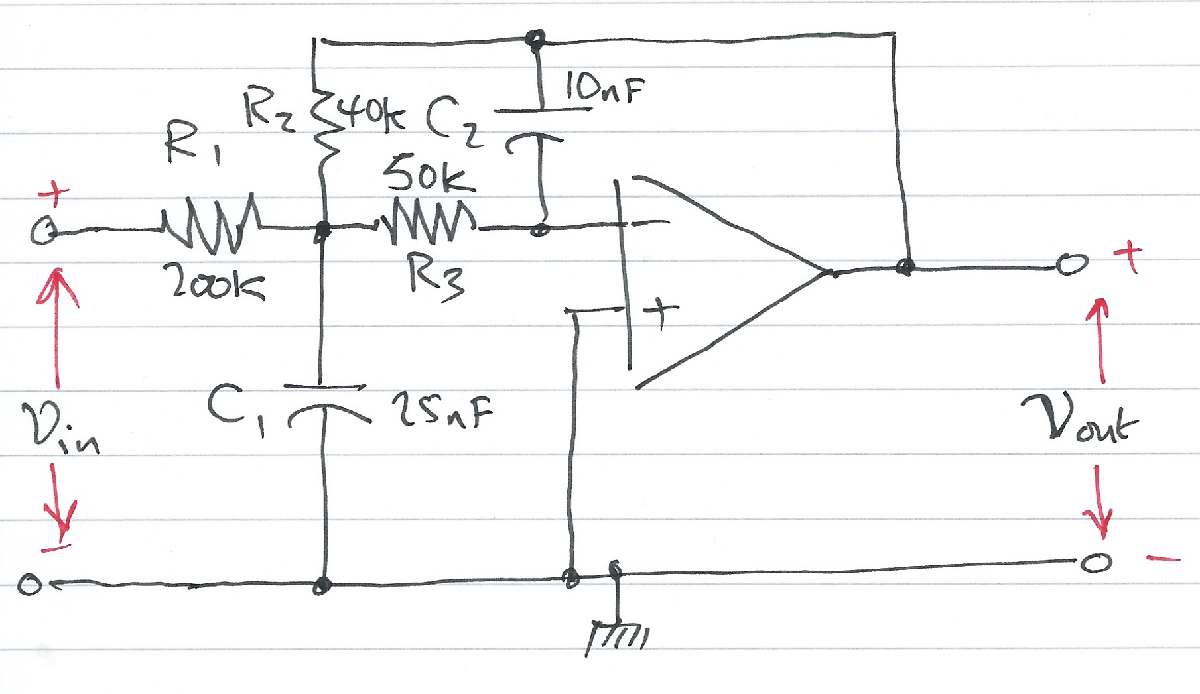

Set up the symbols we will be using. In this case just the Laplace complex frequency $s$.

syms s;

Now define the values of the components

R1 = 200*10^3;
R2 = 40*10^3;
R3 = 50*10^3;

C1 = 25*10^(-9);
C2 = 10*10^(-9);

Define the voltage transfer function


$$G(s) = \frac{V_\mathrm{out}(s)}{V_\mathrm{in}(s)} = \frac{-1}{R_1\left(\left(1/R_1 + 1/R_2 + 1/R_3 + sC_1\right)\left(sC_2R_3\right)+1/R_2\right)}$$


den = R1*((1/R1+ 1/R2 + 1/R3 + s*C1)*(s*R3*C2) + 1/R2);

Simplify coefficients of $s$ in the denominator. Note `sym2poly` converts a symbolic polynomial with numerical coeficients into a MATLAB polynomial.

format long
denG = sym2poly(ans)

denG =    0.000002500000000   0.005000000000000   5.000000000000000


Now define the denominator

numG = -1;

## Plot the frequency response

For convenience, define coefficients $a$ and $b$:

a = denG(1);
b = denG(2);


$$G(j\omega) = \frac{-1}{a\omega^2 - jb\omega + 5}$$


w = 1:10:10000;
Gw = -1./(a*w.^2 - j.*b.*w + 5);

Plot $|G(j\omega )|$ against $\omega \;$on log-lin "graph paper".

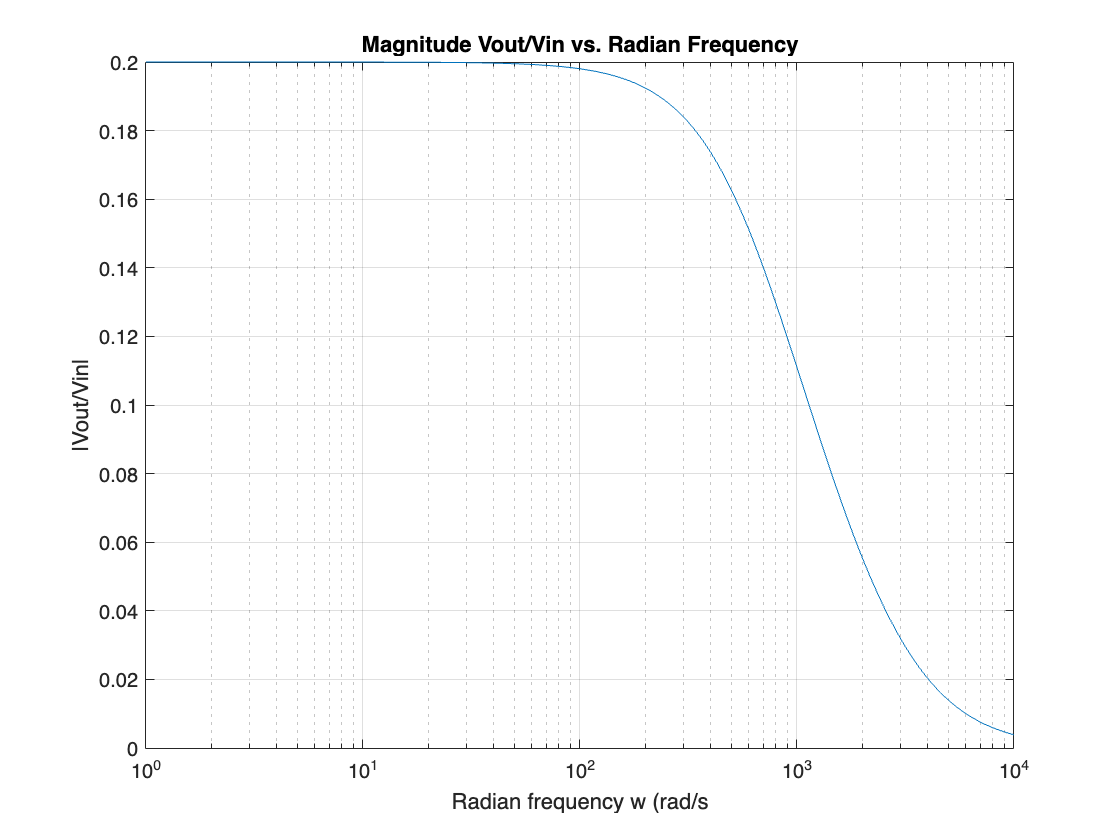

semilogx(w, abs(Gw))
xlabel('Radian frequency w (rad/s')
ylabel('|Vout/Vin|')
title('Magnitude Vout/Vin vs. Radian Frequency')
grid